编写函数时候的测试

x=[27.7;28;29;30];
y=[4.1;4.3;4.1;3];
b=[3 -4];

x_num=size(x,1);
s=zeros(x_num,4);
diffy=diff(y);%y的差 x_num-1列向量
FirstOrder=diffy./diff(x);%1阶差商
for i=1:length(x)-2
    delt2x(i)=x(i+2)-x(i);%这样的方法会自动生成行向量
end
delt2y=diff(FirstOrder);
SecondOrder=delt2y./(delt2x');%2阶差商

% 获取M
    %计算x的差h x_num-1维列向量
    h=diff(x);
    %计算d x_num维列向量
    d=zeros(x_num,1);
    d(1)=6/h(1)*(FirstOrder(1)-b(1));

    d(2:x_num-1)=6*SecondOrder(1:x_num-2);

    d(end)=6/h(3)*(b(2)-FirstOrder(end));
    %计算λ x_num-1维列向量,计算μ x_num-1维列向量
    lambda=zeros(x_num-1,1);
    lambda(1)=1;
    miu=zeros(x_num-1,1);
    miu(end)=1;
    for i=1:size(miu,1)-1
        miu(i)=h(i)/(h(i)+h(i+1));
    end
    for i=2:size(lambda,1)  
        lambda(i)=h(i)/(h(i-1)+h(i));
    end
    
    %用diag拼起来
    A=diag(miu,-1)+diag(2*ones(x_num,1))+diag(lambda,1);
    %求解方程Ax=d 得到M
    M=A^(-1)*d;
%计算多项式系数
s=zeros(x_num-1,4);
syms t;
for i=1:x_num-1
    coef1=M(i)/6/h(i);
    coef2=M(i+1)/6/h(i);
    coef3=(y(i)-M(i)*h(i)^2/6)/h(i);
    coef4=(y(i+1)-M(i+1)*h(i)^2/6)/h(i);
    p=coef1*(-t+x(i+1))^3+coef3*(x(i+1)-t)+coef2*(t-x(i))^3+coef4*(t-x(i));
    p=expand(p)
    p=collect(p);
    p=vpa(p,6)
    s(i,:)=vpa((sym2poly(p)),100);
end

$$p = \frac{36250\,t^{3}}{2727}-\frac{1014820\,t^{2}}{909}+\frac{56818985\,t}{1818}-\frac{7952890039}{27270}$$

$$p = 13.293\,t^{3}-1116.41\,t^{2}+31253.6\,t-291635.0$$

$$p = \frac{73\,t^{3}}{1010}-\frac{2966\,t^{2}}{505}+\frac{160021\,t}{1010}-\frac{1428053}{1010}$$

$$p = 0.0722772\,t^{3}-5.87327\,t^{2}+158.437\,t-1413.91$$

$$p = -\frac{837\,t^{3}}{505}+\frac{146057\,t^{2}}{1010}-\frac{424766\,t}{101}+\frac{4117953}{101}$$

$$p = -1.65743\,t^{3}+144.611\,t^{2}-4205.6\,t+40771.8$$

s = 	1.0e+05 *

    0.0001   -0.0112    0.3125   -2.9164
    0.0000   -0.0001    0.0016   -0.0141
   -0.0000    0.0014   -0.0421    0.4077


函数单元测试  

clc,clear;
x=[27.7;28;29;30];
y=[4.1;4.3;4.1;3];
b=[3 -4];
s = cubic_spline_interplotion(x, y, b)

s = 	1.0e+05 *

    0.0001   -0.0112    0.3125   -2.9164
    0.0000   -0.0001    0.0016   -0.0141
   -0.0000    0.0014   -0.0421    0.4077


s2=cubic_spline_interpolation(x',y',b)

s2 = 	1.0e+05 *

    0.0001   -0.0112    0.3125   -2.9164
    0.0000   -0.0001    0.0016   -0.0141
   -0.0000    0.0014   -0.0421    0.4077


画图

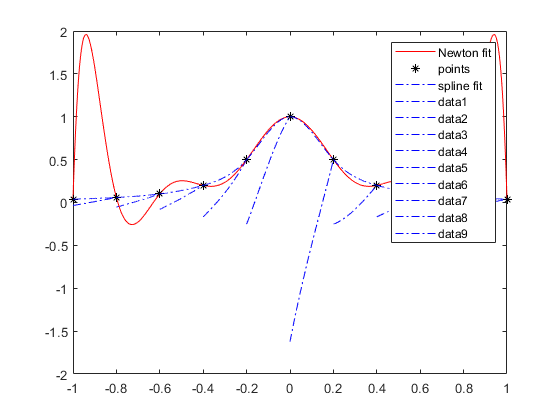

ans =     0.3402
    0.3525


ans =     0.9098
    1.0197


ans =     0.9700
    1.2524


ans =     3.9731
   11.6269


ans =   -11.6574
  -76.8653


ans =    32.0769
    1.9603


ans =     0.1275
    0.5000


ans =     0.3992
    0.5483


ans =     0.5664
    0.6439


ans =     0.2857
    0.2965


clc;clear;
n=10;%numbers of interval
%n=20;
x=[-1:2/n:1];%interpolation data
y=[];%interpolation data
for i=1:1:length(x)
    y=[y 1/(1+25*x(i)^2)];
end
N=my_newton(x,y);
t=linspace(-1,1,1001);%plotting data
Y_Newton=polyval(N,t);
plot(t,Y_Newton,'r-');%newton
hold on;
plot(x,y,'k*');
b=[0.0740,-0.0740];
spline_matrix=cubic_spline_interpolation(x,y,b);
for i=1:1:n%loop to plot the spline func
    tmp_t=linspace(x(i),x(i+1),1001);
    plot(tmp_t,polyval(spline_matrix(i,:),tmp_t),'b-.')
    polyval(spline_matrix(i,:),[y(i) y(i+1)]')
    if i==1
        legend('Newton fit','points','spline fit')
    end
end